clc
clear all
%final- no tocar

m = 100;    %Masa [kg]
c = 6700; %m/(m/s)
k = 2800;   %

H = tf(1,[m c k]);
Gc=tf([4 5 2],[ 2 1 0])

Gc =
 
  4 s^2 + 5 s + 2
  ---------------
     2 s^2 + s
 
Continuous-time transfer function.



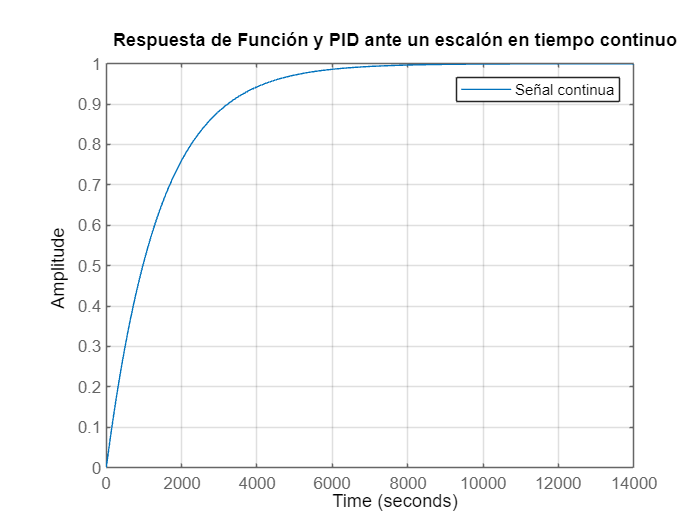

plant=Gc*H/(1+Gc*H);

figure
step(plant);
title('Respuesta de Función y PID ante un escalón en tiempo continuo')
legend('Señal continua');
grid on

stepinfo(plant)

ans = struct with fields:
         RiseTime: 3.0717e+03
    TransientTime: 5.4713e+03
     SettlingTime: 5.4713e+03
      SettlingMin: 0.9044
      SettlingMax: 1.0000
        Overshoot: 0
       Undershoot: 0
             Peak: 1.0000
         PeakTime: 1.4744e+04


asdad

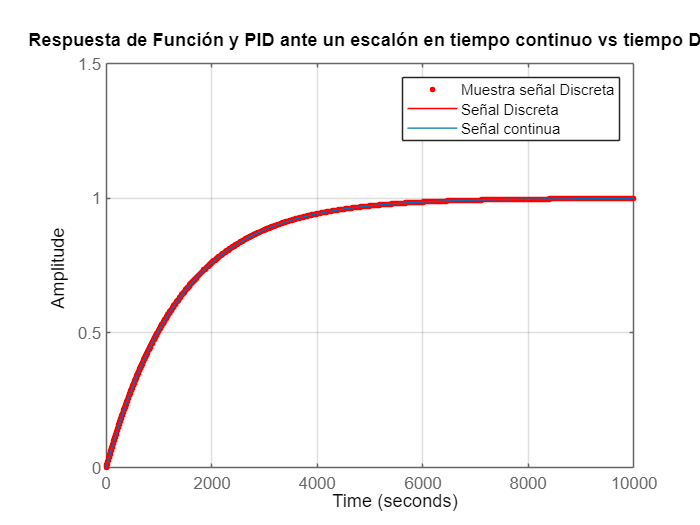

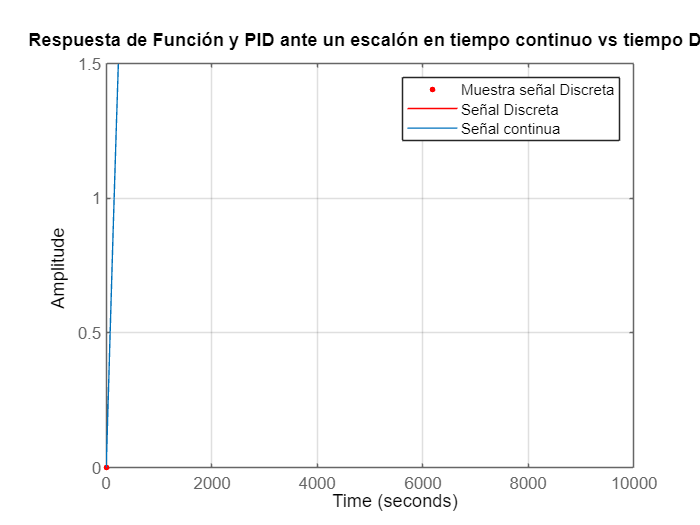

ti = 0; %Tiempo inicial
tf = 10000; %Tiempo final
Ts = 0.1;
t = ti:Ts:tf;
T_k = zeros(1,length(t));

T_k1 = 0;
T_k2 = 0;
F = 1;

U_k=zeros(1,length(t));
U_k1=0;
U_k2=0;

E_k=0;
E_k1=0;
E_k2=0;
ref=1;
sensor=0;

plant_dis=zeros(1,length(t));

for i=2:length(t)
    T_k(i) = (F*(Ts^2) + T_k1*(2*m+Ts*c) - m*T_k2)/(m+Ts*c+(Ts^2)*k);
    T_k2 = T_k1;
    T_k1 = T_k(i);

    E_k = ref - sensor;

    U_k(i) = (E_k*(4+5*Ts+2*Ts^2) - E_k1*(8+5*Ts) + 4*E_k2 + U_k1*(4+Ts) - 2*U_k2) / (2+Ts);
    U_k2=U_k1;

    U_k1=U_k(i);
    E_k2=E_k1;
    E_k1=E_k;
    plant_dis(i)=(T_k(i)*U_k(i));
    sensor=plant_dis(i)  ;

end




figure
plot(t,plant_dis,'.','color','r','MarkerSize',10);
hold on
stairs(t,plant_dis,'color','r');
step(plant);
grid on
title('Respuesta de Función y PID ante un escalón en tiempo continuo vs tiempo Discreto')
legend('Muestra señal Discreta','Señal Discreta', 'Señal continua');
axis([0 tf 0 1.5])

weeee